# Laboratorium 5

# Modulacja Kwadraturowa

### ***ZAD1 SPRAWDZANIE ORTOGONALNOŚCI FUNKCJI***

Sprawdzenie ortogonalności funkcji: sinx, cosx, sin2x, cos2x, … , sin(x+pi/100), sin(x-pi/100) poprzez policzenie iloczynu skalarnego (+analitycznie) z podaniem wartości.

#### Podstawy matematyczne:

**Ortogonalność**  – uogólnienie pojęcia prostopadłości znanego z geometrii euklidesowej na abstrakcyjne przestrzenie z określonym iloczynem skalarnym, jak np. przestrzenie unitarne (w tym przestrzenie Hilberta) czy przestrzenie ortogonalne. Pojęcie ortogonalności bywa uogólnianie również na przestrzenie unormowane w których nie ma naturalnej struktury iloczynu skalarnego.

Aby sprawdzić czy dane wektory są ortogonalne, należy obliczyć ich iloczyn skalarny. Jeżeli iloczyn wyniesie 0, wektory są ortogonalne.

clc; clear; close all;

f = 1;
fs = f * 10;
dt = 1/fs;
t = 0:dt:2/f-1/fs;
x = 2*pi*f*t;

signal1 = sin(x);
signal2 = cos(x);
signal3 = sin(2*x);
signal4 = cos(2*x);
signal5 = sin(x+(pi/100));
signal6 = sin(x-(pi/100));


Wyznaczanie ortogonalności za pomocą funkcji:


ortogonalnosc_1 = dot(signal1, signal2)

ortogonalnosc_1 = 3.2196e-15

ortogonalnosc_2 = dot(signal3, signal4)

ortogonalnosc_2 = -3.8303e-15

ortogonalnosc_3 = dot(signal5, signal6)

ortogonalnosc_3 = 9.9803

Wyznaczanie ortogonalności za pomocą metody analitycznej - polega na tym, że próbkujemy sygnał co π/2, wówczas otrzymujemy wektory np.

sin(x) = [0, 1 , 0 ,-1, 0], cos(x) = [1 , 0, -1, 0, 1], następnie wyliczmy ich iloczyn skalarny i otrzymujemy wynik 0, świadczy to o tym, że są one ortogonalne

### Obserwacje i wnioski:

- Jeśli sygnały są takie same, a ich faza rożni się o 90 stopni, wówczas są ortogonalne.

- Gdy sygnały są ortogonalne funkcja zwraca wartości bliskie zeru, możemy je przybliżyć.

- Nawet niewielkie przesunięcie fazy sprawia, że funkcje już nie są ortogonalne.

## QAM **analogowo **i demodulacja QAM, sprawdzenie wpływu przesunięcia fazowego (symulacja opóźnienia kanału) 

#### Podstawy matematyczne:

Modulacja QAM polega na zakodowaniu sygnału w zmianach amplitud dwóch komponentów przesuniętych względem siebie o 90 stopni.

Matematycznie można przedstawić ją poniższym wzorem:

Funkcje simus oraz cosinus są wzgledem siebie ortogonalne (co wykazało poprzednie zadanie) zatem nie interferują. Skutkuje to powstaniem sygnału o zmodulowanej zarówno amplitudzie jak i fazie. 

Częstotliwość nośnej:

f = 100;
fs = f *100;

Przesunięcie fazowe nośnej sinus:

n = 0;

shift = ((2*pi)/360) * n;

Częstotliwość sygnału pierwszego:

f_s1 = 2;

Częstotliwość sygnału drugiego:

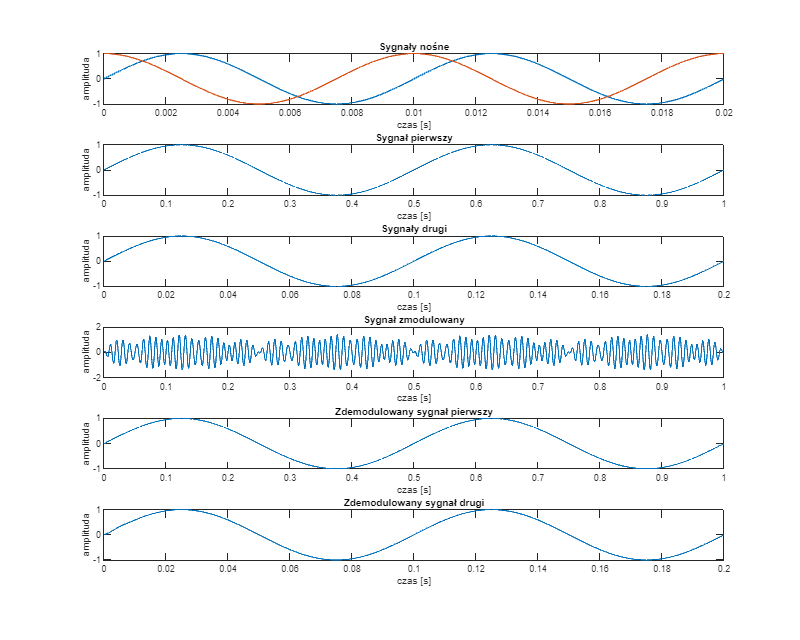

f_s2 = 10;

dt = 1/fs;
t = 0:dt:1-dt;
x = 2*pi*f*t;

%sygnały
n1 = sin(x + shift);
n2 = cos(x);

s1 = sin(2*pi*f_s1*t);
s2 = sin(2*pi*f_s2*t);

s_mod = s1.*n1 + s2.*n2;

%demodulacja
demod_s1 = 2*(lowpass(s_mod .* n1, f, fs, 'Steepness', 0.999));
demod_s2 = 2*(lowpass(s_mod .* n2, f, fs, 'Steepness', 0.999));

%wykresy
fig1 = figure;
fig1.Position = [0, 0, 1000, 800];

subplot(6,1,1)
plot(t, n1, t, n2)
xlim([0, 2/f])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnały nośne')

subplot(6,1,2)
plot(t, s1)
xlim([0, 2/f_s1])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał pierwszy')

subplot(6,1,3)
plot(t, s2)
xlim([0, 2/f_s2])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnały drugi')

subplot(6,1,4)
plot(t, s_mod)
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zmodulowany')

subplot(6,1,5)
plot(t, demod_s1)
xlim([0, 2/f_s1])
xlabel("czas [s]")
ylabel("amplituda")
title('Zdemodulowany sygnał pierwszy')

subplot(6,1,6)
plot(t, demod_s2)
xlim([0, 2/f_s2])
xlabel("czas [s]")
ylabel("amplituda")
title('Zdemodulowany sygnał drugi')

### Obserwacje i wnioski:

- Kiedy funkcje nośne nie są ortogonalne, pojawiają się problemy z demodulacją sygnałów(nachodzą one na siebie)

- Częstotliwość nośnej musi być conajmniej dwa razy większa od najwyższej częstotliwości przenoszonego sygnału.

- Kiedy funkcje są ortogonalne demodulacja przebiega poprawnie.

## **Cyfrowa modulacja 4QAM i 16QAM. Modulacja, demodulacja bezpośrednia, szumy.**

#### **Podstawy matematyczne:**

Schemat modulatora QAM

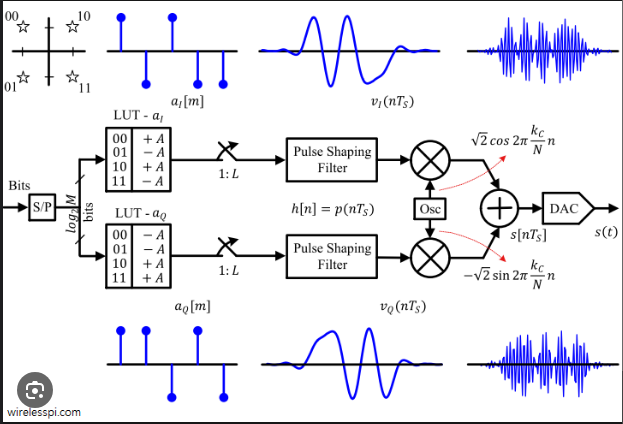

Cyfrowa modulacja QAM polega w pierwszej kolejności na zamianie sygnału cyfrowego na "symbole". Symbol jest sekwencją bitów która odpowiada jednemu 

**Symulacje:**